Proper quantification of simulator dynamics, max motor per end = 1 vs multiple motors per end

**Max 1 motor per end**

rng('default');%initialize RNG for reproducibility

%choose params which support stable tug of war, ie
% high native processivity, low PG unbinding rate eps0<< koff0
% frequent PG binding, pi0>> kOn0
% otherwise based on experimental data rates

motorState.kOn0 = 0.5/60; %rate of single motor (synthase) binding to cargo (mreB) (From Stu data)
motorState.pi0 =10*motorState.kOn0; %single motor binding rate s^-1 %promotes tug of war
motorState.eps0=0.3/60;%single motor unbinding rate s^-1 %promotes tug of war, also at low concentration 
% derived from Stu data)
%processivity is synthesis limited
motorState.kOff0 = 10*motorState.eps0; %rate of single motor (synthase) unbinding from cargo (mreB)
motorState.Fdetach = 1;%detachment force pN nm
motorState.Fstall = 100; %stall force pN nM
motorState.vF=40;%forward velocity nm/s
motorState.vB=0.1;%backward velocity nm/s

motorState.Nplus=0;%initial total number of plus motors 
motorState.Nminus=0;%initial total number of bound plus motors 
motorState.nPlus=0;%number of bound plus motors 
motorState.nMinus=0;%number of bound minus motors

simPar.nStep= 100;
simPar.doFixedTime=true;
simPar.simTime = 5000;

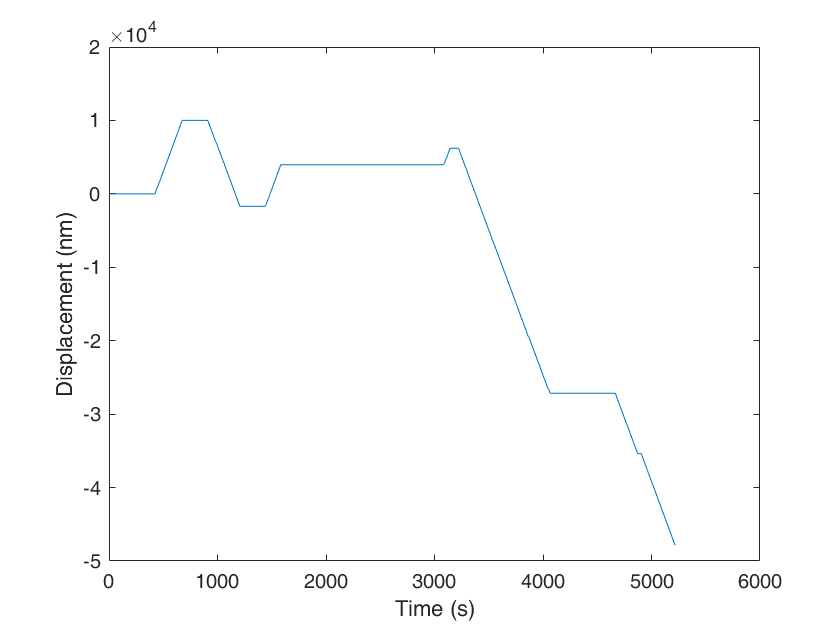

%Nmax = 1 each side (max number of motors), low concentration, which should give frequent pausing model
motorState.Nmax = 1;
motorState.motorConcentration =0.1;%arb units, essentiall scaling of low synthase concentration data here


[dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
t=dynamics.t;
x=dynamics.x;
figure;
plot(t,x);
ylabel('Displacement (nm)');
xlabel('Time (s)');

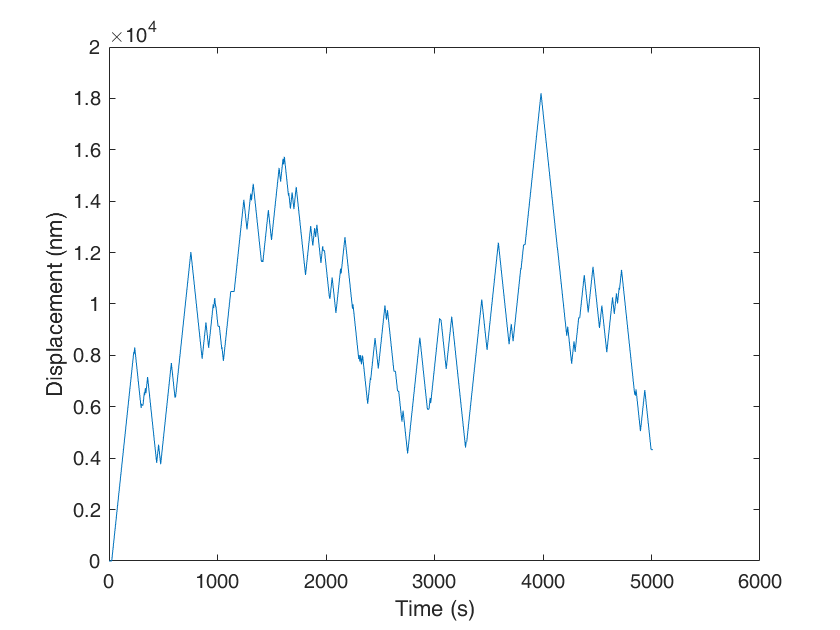

%Nmax = 1 each side, high concentration,  which should give frequent reversals
motorState.Nmax = 1;
motorState.motorConcentration =10;%arb units, essentiall scaling of low synthase concentration data here


[dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
t=dynamics.t;
x=dynamics.x;
figure;
plot(t,x);
ylabel('Displacement (nm)');
xlabel('Time (s)');

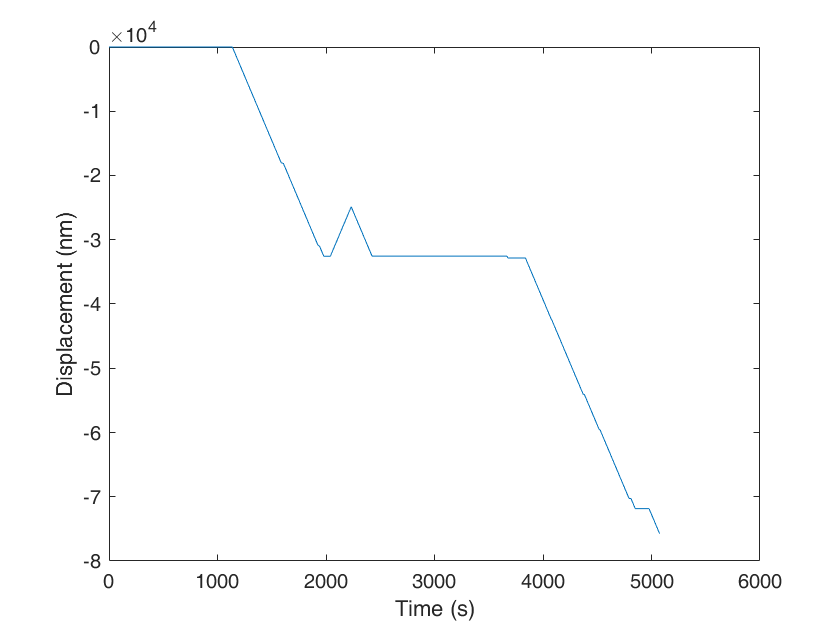

%Nmax = inf each side, low concentration which should give frequent pausing
motorState.Nmax = inf;
motorState.motorConcentration =0.1;%arb units, essentiall scaling of low synthase concentration data here
[dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
t=dynamics.t;
x=dynamics.x;
figure;
plot(t,x);
ylabel('Displacement (nm)');
xlabel('Time (s)');

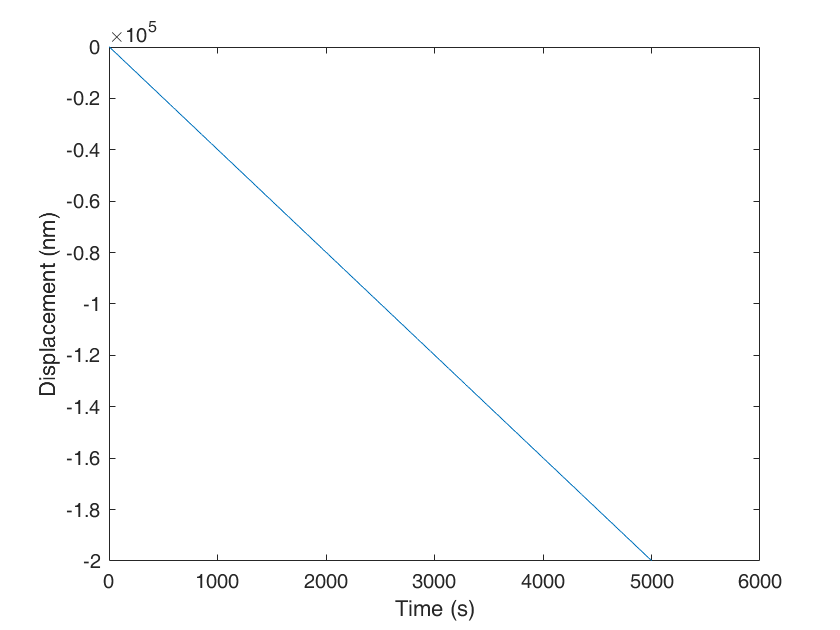

%Nmax = inf each side, high concentration which lipowski predicts should give
%infrequent pausing, relatively infrequent reversals but high processivity
motorState.Nmax = inf;
motorState.motorConcentration =10;%arb units, essentiall scaling of low synthase concentration data here
[dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
t=dynamics.t;
x=dynamics.x;
figure;
plot(t,x);
ylabel('Displacement (nm)');
xlabel('Time (s)');

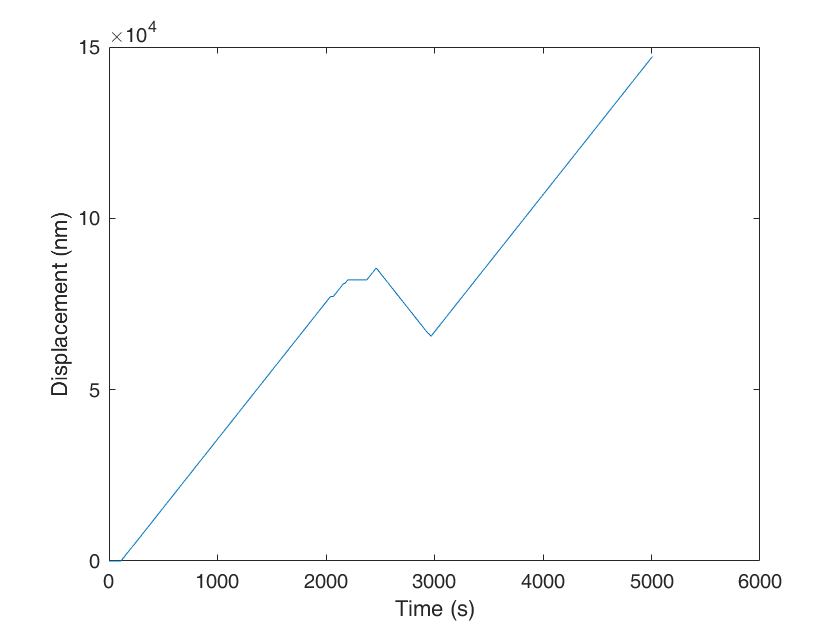

%Nmax = inf each side, intermediate concentration which lipowski should
%give some tug of war
motorState.Nmax = inf;
motorState.motorConcentration =1;%arb units, essentiall scaling of low synthase concentration data here
[dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
t=dynamics.t;
x=dynamics.x;
figure;
plot(t,x);
ylabel('Displacement (nm)');
xlabel('Time (s)');

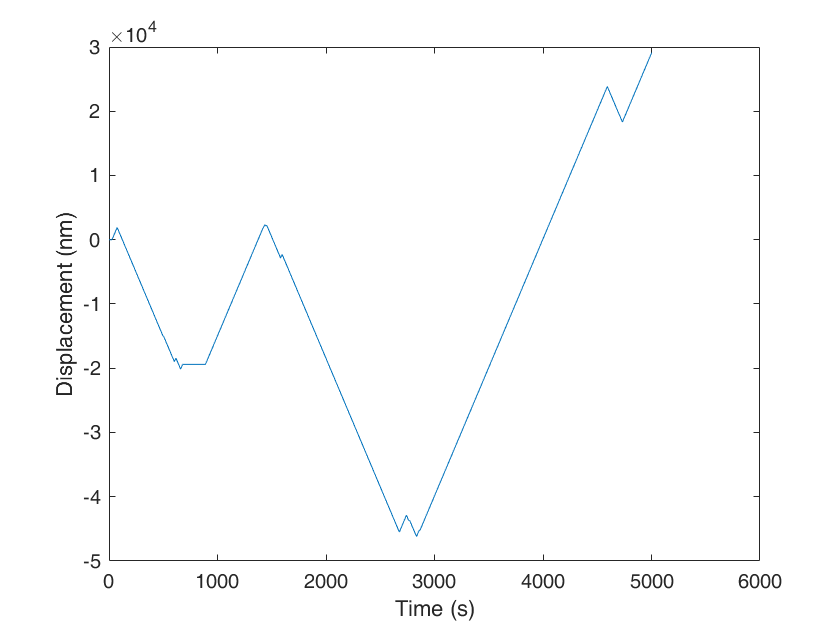

%and again
motorState.Nmax = inf;
motorState.motorConcentration =1;%arb units, essentiall scaling of low synthase concentration data here
[dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
t=dynamics.t;
x=dynamics.x;
figure;
plot(t,x);
ylabel('Displacement (nm)');
xlabel('Time (s)');

**initial rates etc analysis**

motorConcRange = 10.^(0:4).*0.01

motorConcRange =     0.0100    0.1000    1.0000   10.0000  100.0000



analysisPar.frameInterval = 6;
analysisPar.zeroSpeedThresh = 5;
analysisPar.switchTooCloseThresh = 4;
nSimRepeat=100

nSimRepeat = 100

**Max motor = 1**

motorState.Nmax = 1;

for ii = 1:numel(motorConcRange)
    motorState.motorConcentration =motorConcRange(ii);
    [processivityNmax1{ii}, speedNmax1{ii}, lifetimeNmax1{ii}, rateNmax1{ii}, fractionMotileNmax1(ii,:), simResultNmax1{ii},NmotorNmax1{ii}] =...
     quantifySimDynamics(motorState, simPar,analysisPar,nSimRepeat);
   lifetimeAllNmax1{ii} = lifetimeNmax1{ii}.All;
   lifetimeProcessiveNmax1{ii} = lifetimeNmax1{ii}.Processive;
   lifetimeStaticNmax1{ii} = lifetimeNmax1{ii}.Static;
end

%make the plots
fieldName={'c1','c2','c3','c4','c5'};
%categoryName={'10^-2', '10^-1','10^0','10^1','10^2'};
categoryName={'10^0', '10^1','10^2','10^3','10^4'};

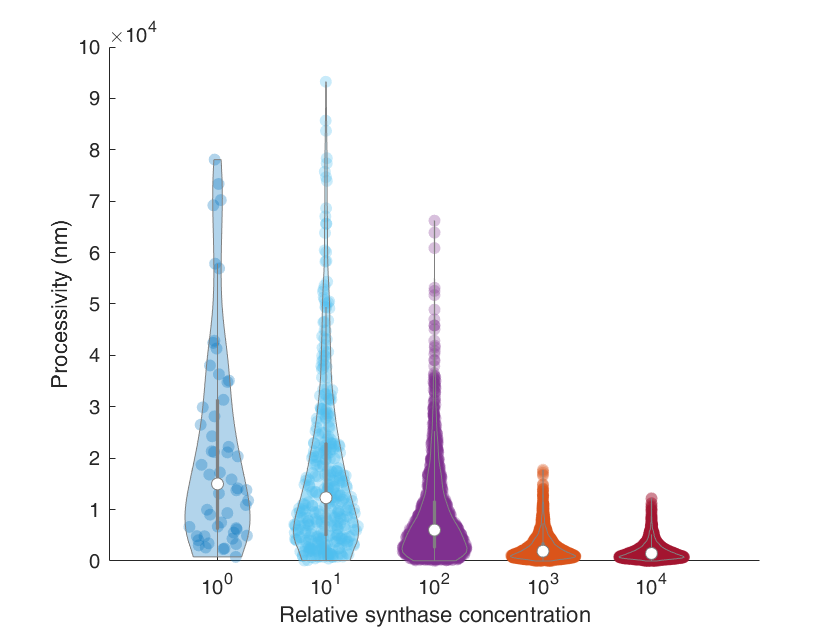


figure;
violinplot(cell2struct(processivityNmax1,fieldName,2));
xlabel('Relative synthase concentration');
ylabel('Processivity (nm)');
hA=gca;
hA.XTickLabel=categoryName;

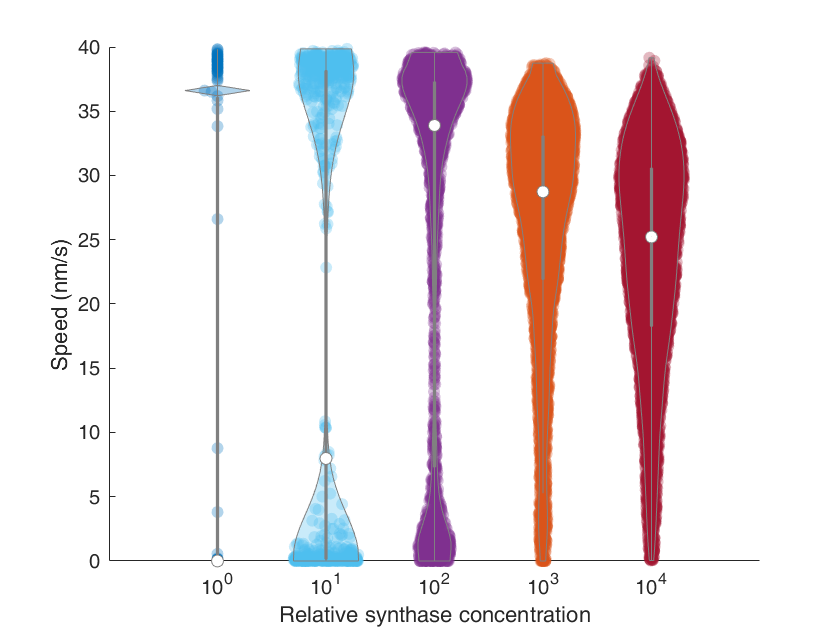

%probably dont expect speed to be affected based on current sim parameters
figure;
violinplot(cell2struct(speedNmax1,fieldName,2));
xlabel('Relative synthase concentration');
ylabel('Speed (nm/s)');
hA=gca;
hA.XTickLabel=categoryName;

Well that's me surprised then I guess

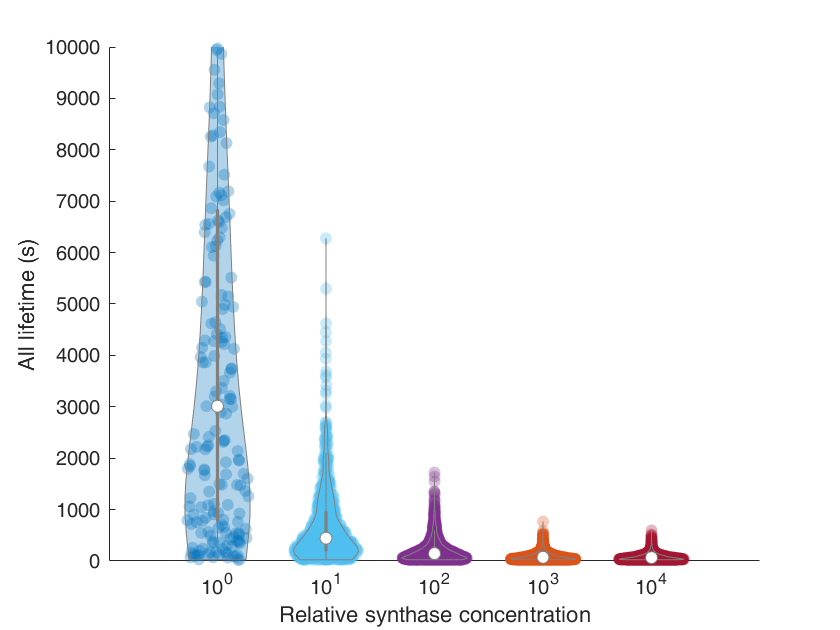


%total lifetime
figure;
violinplot(cell2struct(lifetimeAllNmax1,fieldName,2));
xlabel('Relative synthase concentration');
ylabel('All lifetime (s)');
ylim([0 10e3])
hA=gca;
hA.XTickLabel=categoryName;

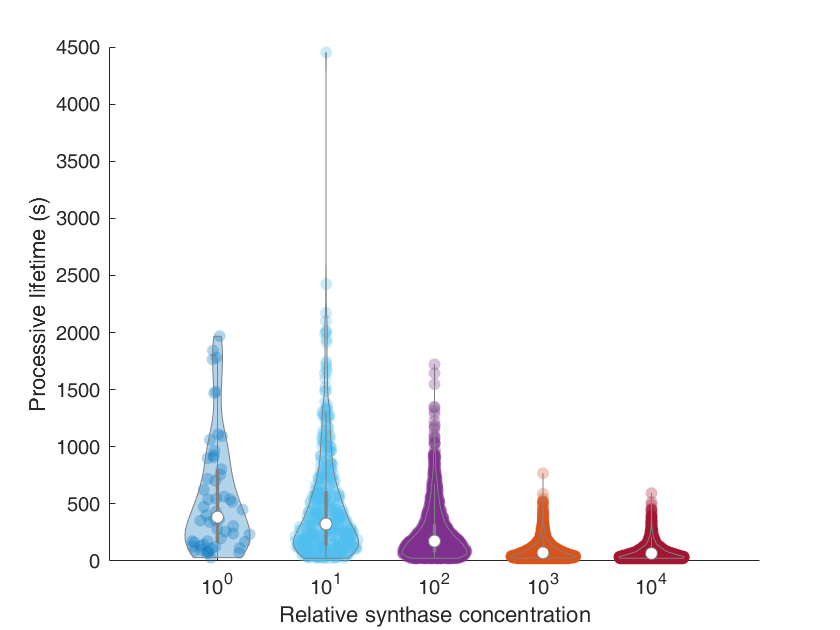

%processive lifetime
figure;
violinplot(cell2struct(lifetimeProcessiveNmax1,fieldName,2));
xlabel('Relative synthase concentration');
ylabel('Processive lifetime (s)');
hA=gca;
hA.XTickLabel=categoryName;

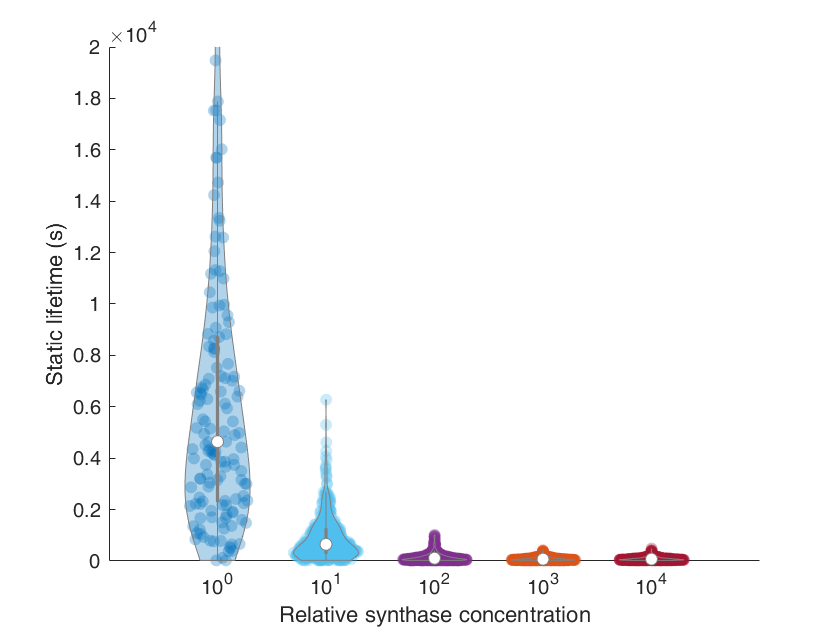

%static lifetime
figure;
violinplot(cell2struct(lifetimeStaticNmax1,fieldName,2));
xlabel('Relative synthase concentration');
ylabel('Static lifetime (s)');
ylim([0 20e3])
hA=gca;
hA.XTickLabel=categoryName;

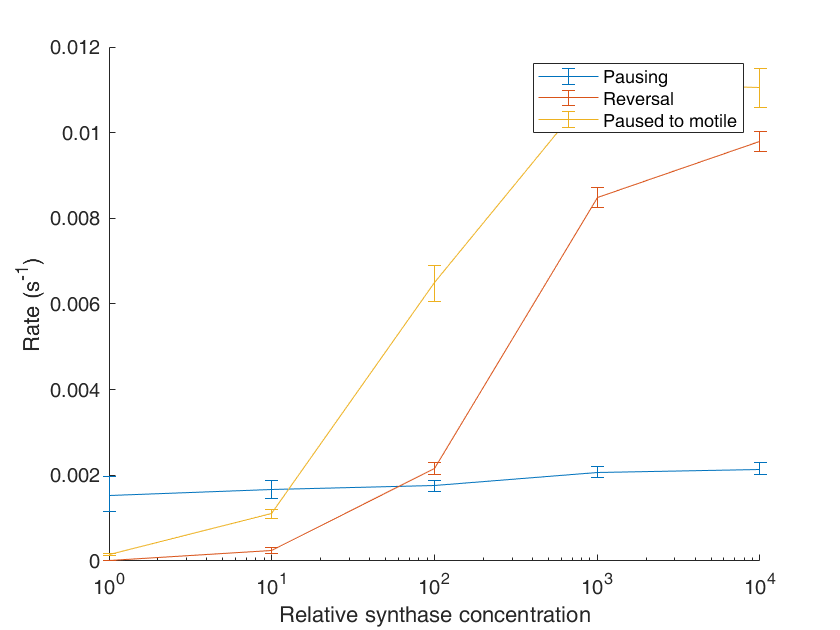

%rates
for ii = 1:numel(motorConcRange)
    pause_processive(ii,:) = rateNmax1{ii}.pause_processive;
    reversal_processive(ii,:) = rateNmax1{ii}.reversal_processive;
    staticToMotile(ii,:) = rateNmax1{ii}.staticToMotile;
end

figure;
hold all;
errorbar(motorConcRange*1e2, pause_processive(:,1),...
    pause_processive(:,1)-pause_processive(:,2),pause_processive(:,3)-pause_processive(:,1));
errorbar(motorConcRange*1e2, reversal_processive(:,1),...
    reversal_processive(:,1)-reversal_processive(:,2),reversal_processive(:,3)-reversal_processive(:,1));
errorbar(motorConcRange*1e2, staticToMotile(:,1),...
    staticToMotile(:,1)-staticToMotile(:,2),staticToMotile(:,3)-staticToMotile(:,1));
hA=gca;
hA.XScale='log';
legend('Pausing','Reversal','Paused to motile');
xlabel('Relative synthase concentration');
ylabel('Rate (s^{-1})')

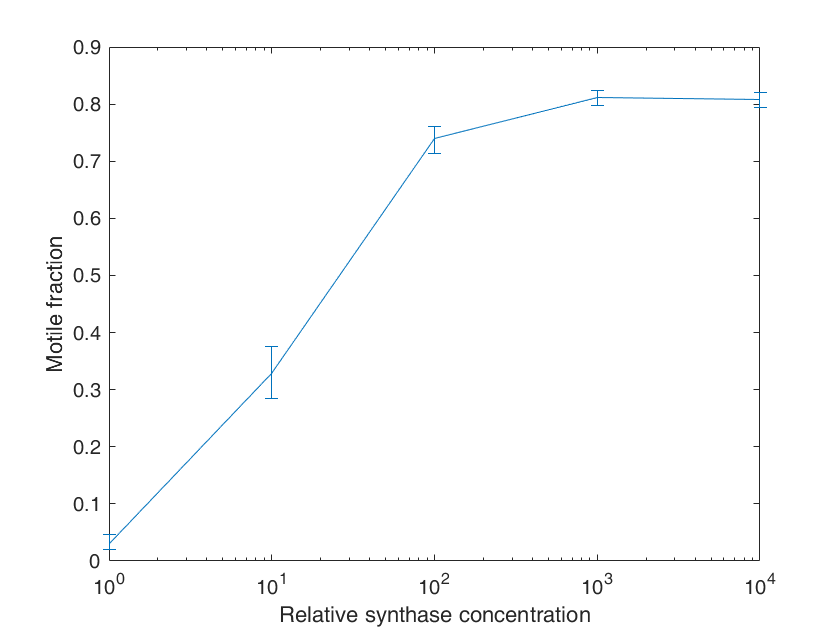

%faction motile v static
figure;
errorbar(motorConcRange*1e2, fractionMotileNmax1(:,1),...
    fractionMotileNmax1(:,1)-fractionMotileNmax1(:,2),fractionMotileNmax1(:,3)-fractionMotileNmax1(:,1));
hA=gca;
hA.XScale='log';
xlabel('Relative synthase concentration');
ylabel('Motile fraction')

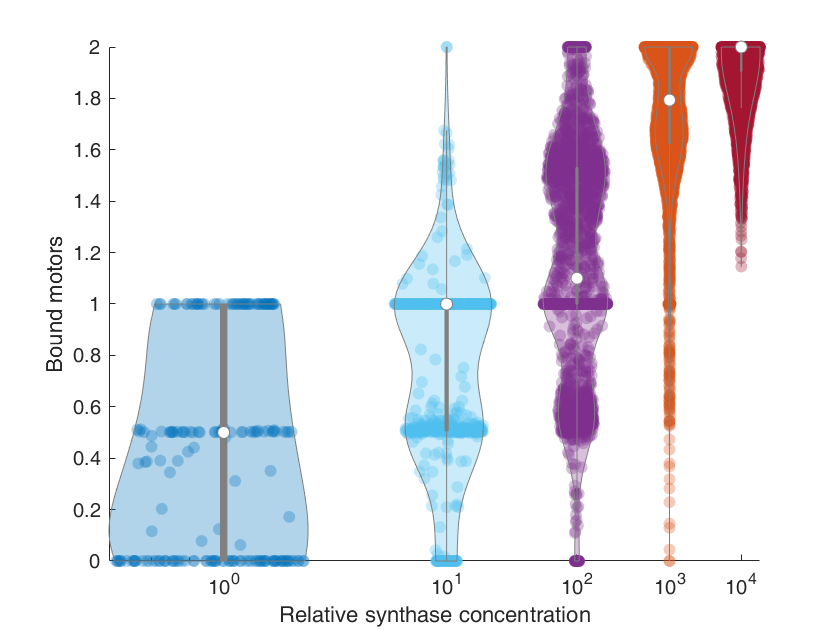


%motor loading
figure;
violinplot(cell2struct(NmotorNmax1,fieldName,2));
hA=gca;
hA.XScale='log';
hA.XTickLabel=categoryName;
xlabel('Relative synthase concentration');
ylabel('Bound motors')

**Max motor = inf**

motorState.Nmax = inf;

for ii = 1:numel(motorConcRange)
    motorState.motorConcentration =motorConcRange(ii);
    [processivityNmaxInf{ii}, speedNmaxInf{ii}, lifetimeNmaxInf{ii}, rateNmaxInf{ii}, fractionMotileNmaxInf(ii,:), simResultNmaxInf{ii}, NmotorNmaxInf{ii}] =...
     quantifySimDynamics(motorState, simPar,analysisPar,nSimRepeat);
   lifetimeAllNmaxInf{ii} = lifetimeNmaxInf{ii}.All;
   lifetimeProcessiveNmaxInf{ii} = lifetimeNmaxInf{ii}.Processive;
   lifetimeStaticNmaxInf{ii} = lifetimeNmaxInf{ii}.Static;
end

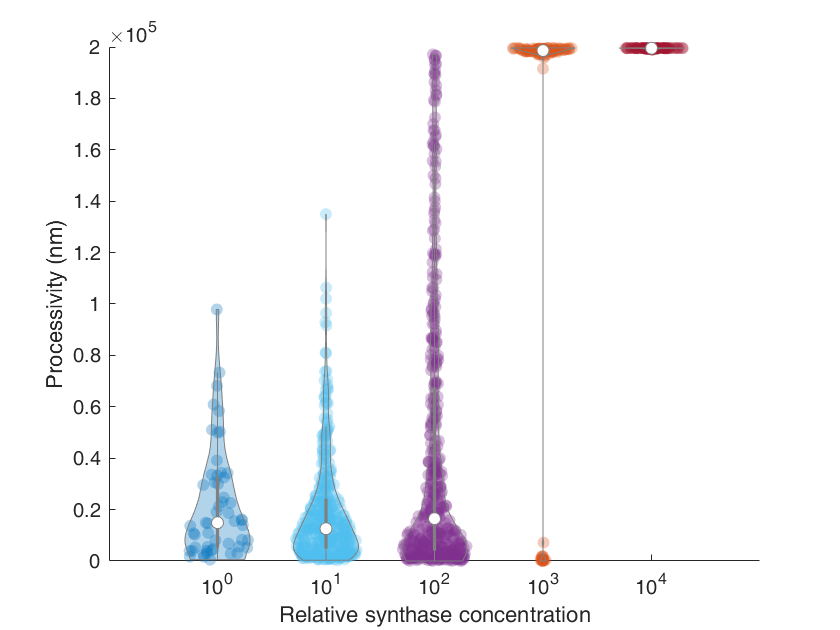


%make the plots
fieldName={'c1','c2','c3','c4','c5'};
%categoryName={'10^-2', '10^-1','10^0','10^1','10^2'};
categoryName={'10^0', '10^1','10^2','10^3','10^4'};

figure;
violinplot(cell2struct(processivityNmaxInf,fieldName,2));
xlabel('Relative synthase concentration');
ylabel('Processivity (nm)');
hA=gca;
hA.XTickLabel=categoryName;

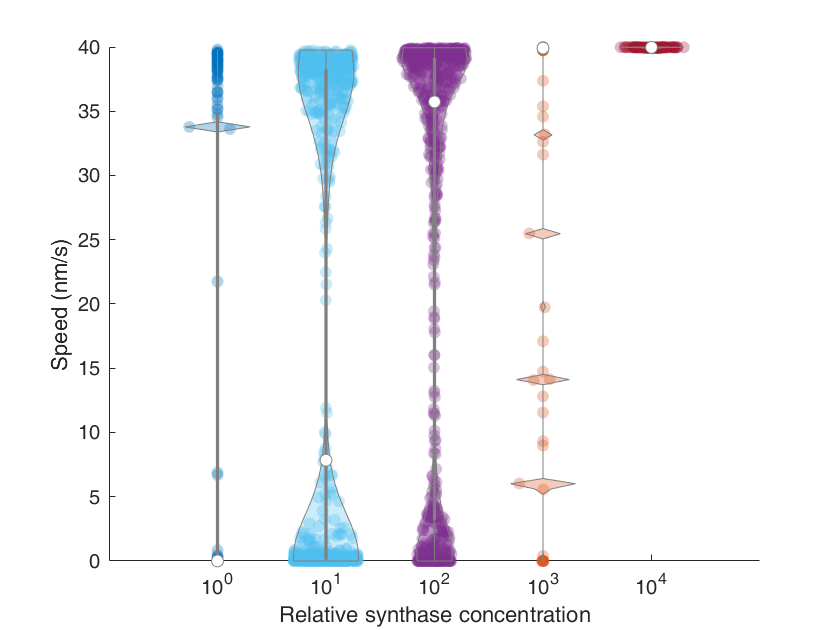

%probably dont expect speed to be affected based on current sim parameters
figure;
violinplot(cell2struct(speedNmaxInf,fieldName,2));
hA=gca;
hA.XTickLabel=categoryName;
xlabel('Relative synthase concentration');
ylabel('Speed (nm/s)');

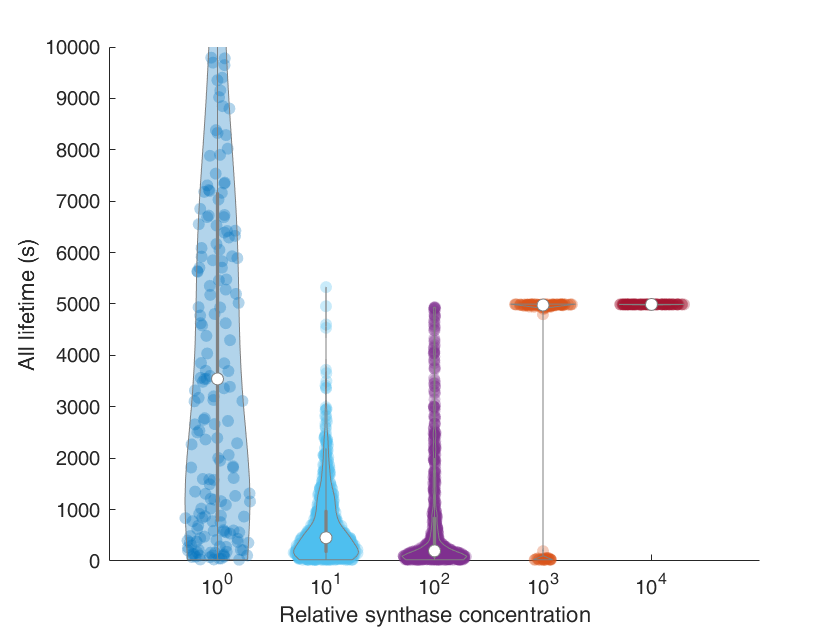


%total lifetime
figure;
violinplot(cell2struct(lifetimeAllNmaxInf,fieldName,2));
xlabel('Relative synthase concentration');
ylabel('All lifetime (s)');
ylim([0 10e3])
hA=gca;
hA.XTickLabel=categoryName;

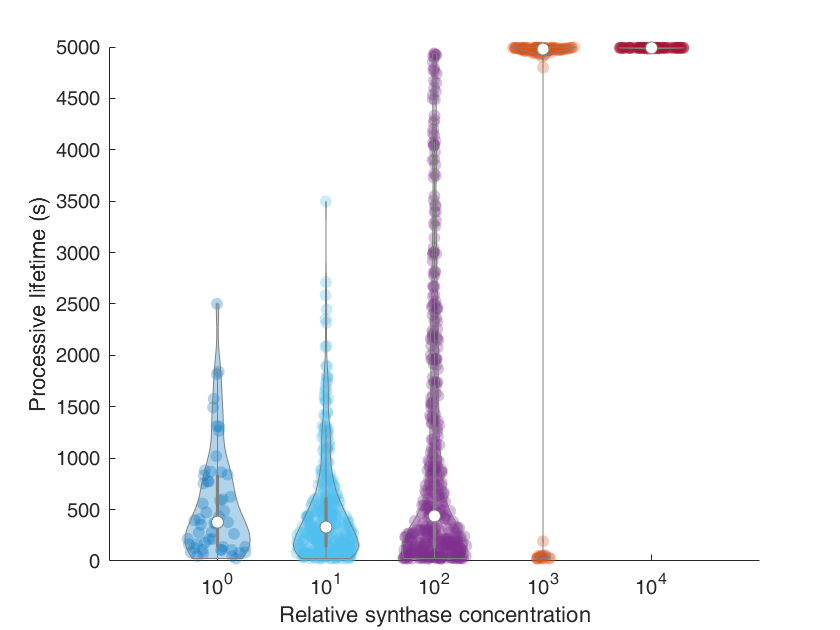

%processive lifetime
figure;
violinplot(cell2struct(lifetimeProcessiveNmaxInf,fieldName,2));
xlabel('Relative synthase concentration');
ylabel('Processive lifetime (s)');
hA=gca;
hA.XTickLabel=categoryName;

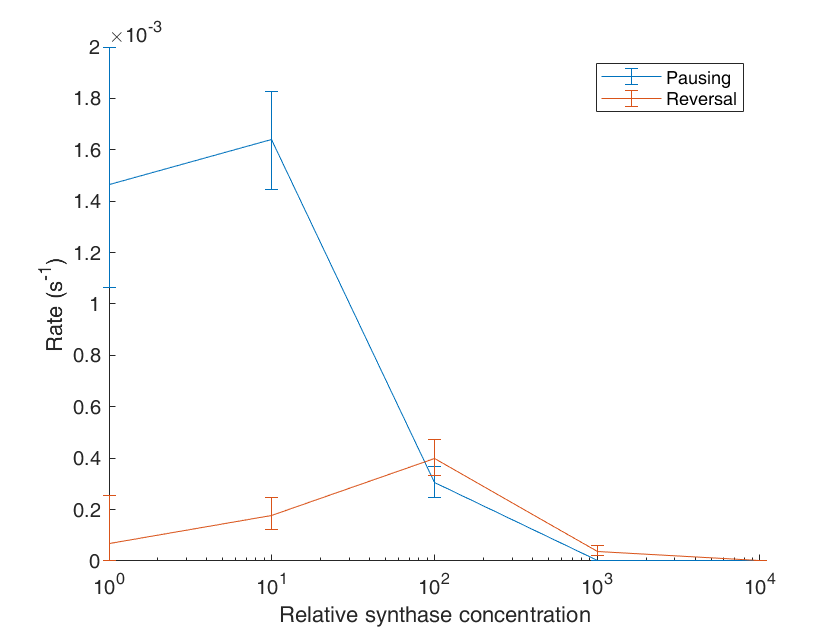

% %static lifetime
% figure;
% violinplot(cell2struct(lifetimeStaticNmaxInf,fieldName,2));
% xlabel('Relative synthase concentration');
% ylabel('Static lifetime (s)');
% ylim([0 20e3])

%rates
for ii = 1:numel(motorConcRange)
    pause_processive(ii,:) = rateNmaxInf{ii}.pause_processive;
    reversal_processive(ii,:) = rateNmaxInf{ii}.reversal_processive;
    staticToMotile(ii,:) = rateNmaxInf{ii}.staticToMotile;
end

figure;
hold all;
errorbar(motorConcRange*1e2, pause_processive(:,1),...
    pause_processive(:,1)-pause_processive(:,2),pause_processive(:,3)-pause_processive(:,1));
errorbar(motorConcRange*1e2, reversal_processive(:,1),...
    reversal_processive(:,1)-reversal_processive(:,2),reversal_processive(:,3)-reversal_processive(:,1));
hA=gca;
hA.XScale='log';
legend('Pausing','Reversal');
xlabel('Relative synthase concentration');
ylabel('Rate (s^{-1})')

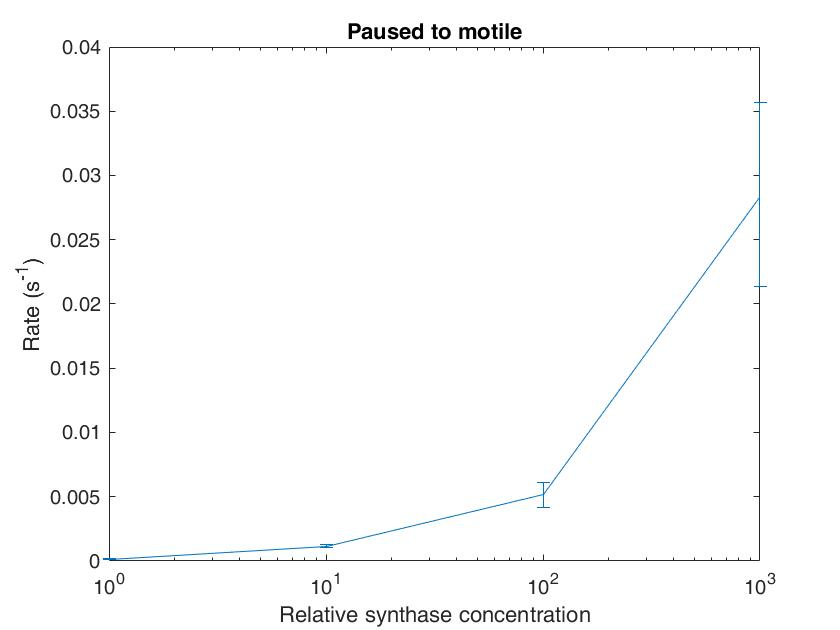

figure;
errorbar(motorConcRange*1e2, staticToMotile(:,1),...
    staticToMotile(:,1)-staticToMotile(:,2),staticToMotile(:,3)-staticToMotile(:,1));
hA=gca;
hA.XScale='log';
title('Paused to motile')
xlabel('Relative synthase concentration');
ylabel('Rate (s^{-1})')

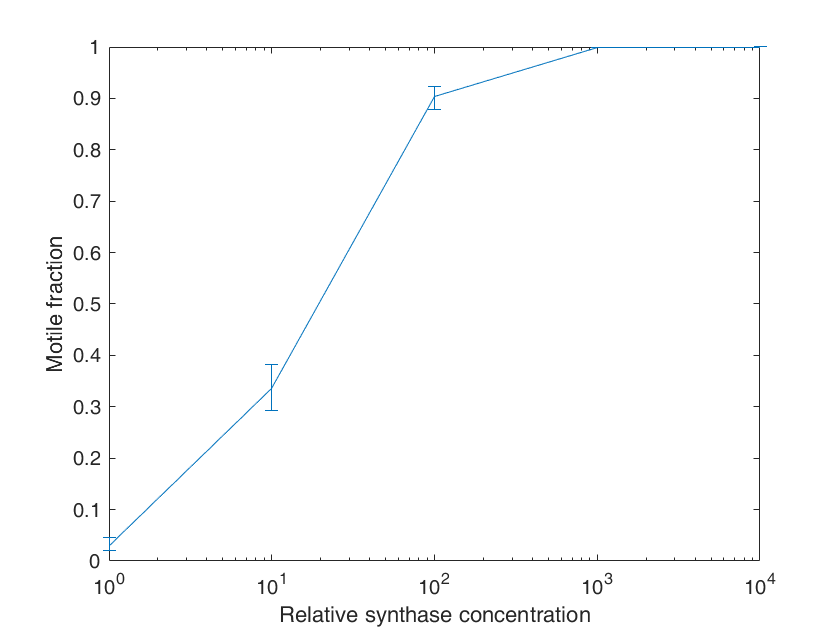


%faction motile v static
figure;
errorbar(motorConcRange*1e2, fractionMotileNmaxInf(:,1),...
    fractionMotileNmaxInf(:,1)-fractionMotileNmaxInf(:,2),fractionMotileNmaxInf(:,3)-fractionMotileNmaxInf(:,1));
hA=gca;
hA.XScale='log';
xlabel('Relative synthase concentration');
ylabel('Motile fraction')

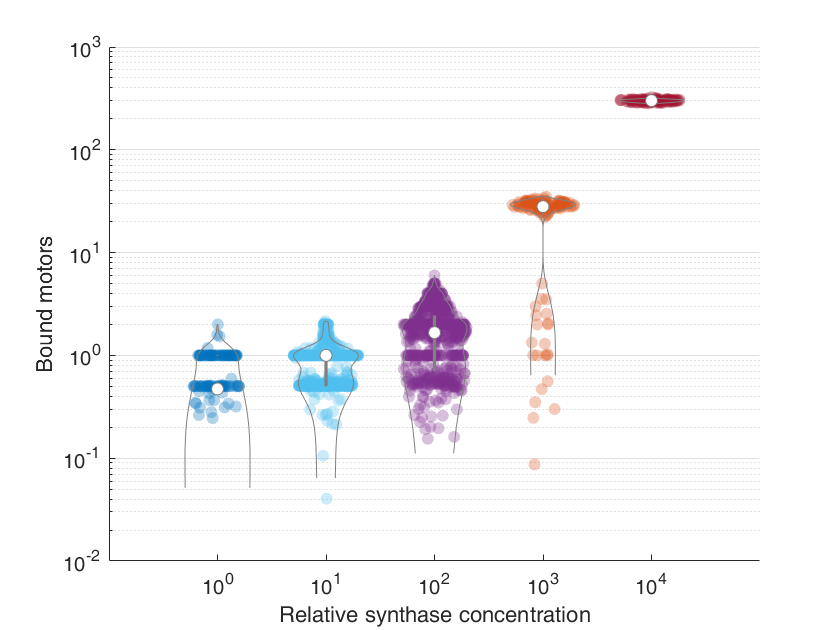


%motor loading
figure;
violinplot(cell2struct(NmotorNmaxInf,fieldName,2));
hA=gca;
hA.YScale='log';
hA.YGrid='on';
xlabel('Relative synthase concentration');
ylabel('Bound motors')
hA.XTickLabel=categoryName;

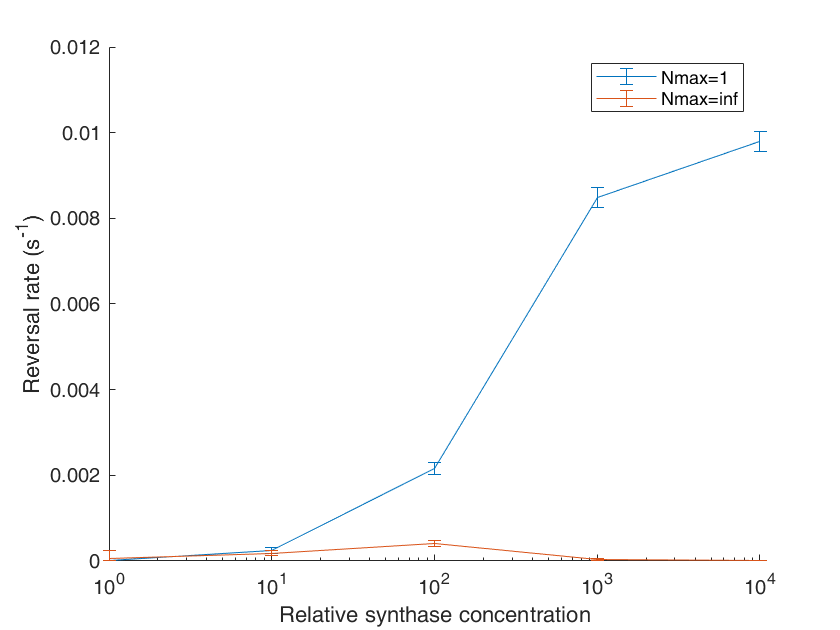

%rates
for ii = 1:numel(motorConcRange)
    pause_processive1(ii,:) = rateNmax1{ii}.pause_processive;
    reversal_processive1(ii,:) = rateNmax1{ii}.reversal_processive;
    staticToMotile1(ii,:) = rateNmax1{ii}.staticToMotile;
end

figure;
hold all;
errorbar(motorConcRange*1e2, reversal_processive1(:,1),...
    reversal_processive1(:,1)-reversal_processive1(:,2),reversal_processive1(:,3)-reversal_processive1(:,1));
errorbar(motorConcRange*1e2, reversal_processive(:,1),...
    reversal_processive(:,1)-reversal_processive(:,2),reversal_processive(:,3)-reversal_processive(:,1));
reversal_processiveInf=reversal_processive;
pause_processiveInf=pause_processive;
staticToMotileInf=staticToMotile;

hA=gca;
hA.XScale='log';
legend('Nmax=1','Nmax=inf');
xlabel('Relative synthase concentration');
ylabel('Reversal rate (s^{-1})')
save('lipowskiSimInitialResults220310.mat')